# simulate the forward imaging process of label-free SFS imaging and recover a super-resolution imaging 

close all;clear;clc;
addpath(genpath('./XxUtils'));

## simulate the high resoluiton complex object

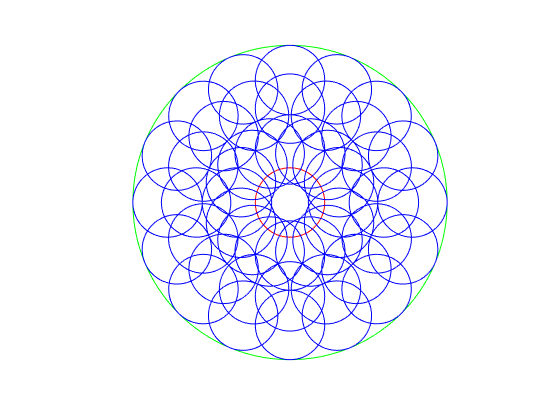

TestSavePath = '../dataset/test/Result'; 
DataGTPath = '../dataset/test/MixedDataset/input_gt_images';
data = '12.16';
name = 'traditionalmodel-full-2';

NA=0.85;           %numerical aperture
lamda=660e-9;      % illumination wavelength
cutoffFrequency = 2 * pi/lamda * NA;
N = [1.3 2.3 3];    %effective index
illumSteps =[16 16 16]; % directions of illumination
phi = [0 0 0]/180*pi; %initial phase
ke = N.*2*pi/lamda;
scale_factor = 2;
a = 0.050227;
spsize = a*lamda/NA;        % actual size of each captured image unit
psize = spsize/scale_factor;% size of each SR image unit

%set the parament of reconstruction parament
test_groups_number = 151:152;
%paint the spectrum schematic
spectrum=impaint(N(end),lamda,cutoffFrequency,ke,phi,illumSteps);

imwrite(spectrum,'spectrum.tif');

save_test_path = [TestSavePath '\' data '\' name];
% if exist(save_test_path,'dir'), rmdir(save_test_path,'s'); end
mkdir(save_test_path);

resolution=lamda/(NA+max(N));disp(resolution*1e9);

  171.4286



## generate the low-pass filtered images

files_gt = XxSort(XxDir(DataGTPath, '*'));
msssim= zeros([1 length(test_groups_number)]);
nrmse=zeros([1 length(test_groups_number)]);
Psnr= zeros([1 length(test_groups_number)]);
time= zeros([1 length(test_groups_number)]);
for kkk = test_groups_number    
    object_original = imread(files_gt{kkk});% read original images
    objectAmplitude = double(object_original);
    object = objectAmplitude;
    [m,n,l] = size(object); % image size of high resolution object
    m1 = m/(spsize/psize);n1 = n/(spsize/psize); % image size of the final output 
    imSeqLowRes = zeros(m1, n1, length(ke),max(illumSteps)); 
    dkx = 2*pi/(psize*n);
    dky = 2*pi/(psize*m);
    kmax = pi/spsize;
    [kxm,kym] = meshgrid(-kmax:kmax/((m1-1)/2):kmax,-kmax:kmax/((n1-1)/2):kmax);
    CTF = ((kxm.^2+kym.^2)<cutoffFrequency^2); % pupil function circ(kmax); no aberration
    objectFT = fftshift(fft2(object));

% From here, the light is center light to illuminate the sample
    kxc = round((n+1)/2);    
    kyc = round((m+1)/2);
    kyl = round(kyc-(m1-1)/2); kyh = round(kyc+(m1-1)/2);
    kxl = round(kxc-(n1-1)/2); kxh = round(kxc+(n1-1)/2);
    imWhiteLowFT = objectFT(kyl:kyh,kxl:kxh).*CTF;
    imWhiteLowRes = abs(ifft2(ifftshift(imWhiteLowFT))).^2;
    maxValue = max(max(imWhiteLowRes));
% From here, different-grating to illuminate the sample
 for kt = 1:length(ke)
    tt1 = illumSteps(kt);
    theta2 = phi(kt) : 2*pi/illumSteps(kt) : 2*pi.*(illumSteps(kt)-1)/illumSteps(kt)+phi(kt); %每圈的照明角度
    for tt = 1:tt1
        
        kex = ke(kt) * cos(theta2(tt));
        key = ke(kt) * sin(theta2(tt));        
        kxc = round((n+1)/2+kex/dkx);
        kyc = round((m+1)/2+key/dky);
        kyl = round(kyc-(m1-1)/2); kyh = round(kyc+(m1-1)/2);
        kxl = round(kxc-(n1-1)/2); kxh = round(kxc+(n1-1)/2);
        imSeqLowFT =  objectFT(kyl:kyh,kxl:kxh).*CTF;
        imSeqLowRes(:,:,kt,tt) = abs(ifft2(ifftshift(imSeqLowFT))).^2;
        im = imSeqLowRes(:,:,kt,tt);
    end
end

## recover the super-resolution image

tic 
loop = 200   
reconstruction = zeros(m,n,loop);  %the box to record reconstructed images
objectRecover = zeros(m,n);
objectRecoverFT = fftshift(fft2(objectRecover));
for tl = 1:loop
    kxc = round((n+1)/2);
    kyc = round((m+1)/2);
    kyl = round(kyc-(m1-1)/2); kyh = round(kyc+(m1-1)/2);
    kxl = round(kxc-(n1-1)/2); kxh = round(kxc+(n1-1)/2);
    lowResFT = objectRecoverFT(kyl:kyh,kxl:kxh).*CTF;
    im_lowRes = ifft2(ifftshift(lowResFT));
    im_lowRes = sqrt(imWhiteLowRes).*exp(1i.*angle(im_lowRes));
    lowResFT = fftshift(fft2(im_lowRes)).*CTF;
    objectRecoverFT(kyl:kyh,kxl:kxh) = (1-CTF).*objectRecoverFT(kyl:kyh,kxl:kxh) + lowResFT;
     
    for te = 1:length(ke)
        pp1 = illumSteps(te);
        theta2 = phi(te) : 2*pi/illumSteps(te) : 2*pi.*(illumSteps(te)-1)/illumSteps(te)+phi(te); %每圈的照明角度
        for pp = 1:pp1
            
            kex = ke(te) * cos(theta2(pp));
            key = ke(te) * sin(theta2(pp)); 
            kxc = round((n+1)/2+kex/dkx);
            kyc = round((m+1)/2+key/dky);
            kyl = round(kyc-(m1-1)/2); kyh = round(kyc+(m1-1)/2);
            kxl = round(kxc-(n1-1)/2); kxh = round(kxc+(n1-1)/2);
            lowResFT =  objectRecoverFT(kyl:kyh,kxl:kxh).*CTF;
            im_lowRes = ifft2(ifftshift(lowResFT));
            im_lowRes = sqrt(imSeqLowRes(:,:,te,pp)).*exp(1i.*angle(im_lowRes));
            lowResFT = fftshift(fft2(im_lowRes)).*CTF;
            objectRecoverFT(kyl:kyh,kxl:kxh) = (1-CTF).*objectRecoverFT(kyl:kyh,kxl:kxh) + lowResFT;
        end
    end
        reconstruction(:,:,tl) = objectRecoverFT;  % record the reconstructed image in every loop
end
toc
time(kkk)=toc;

## plot the eps

for s= 1:loop-1
    eps(s) = sum(sum((abs(reconstruction(:,:,s+1))-abs(reconstruction(:,:,s))).^2)); 
end
%figure; plot(eps);  %figure5
title('Convergence of the iteration');xlabel('steps');ylabel('error');
saveas(gcf,'Convergence of the iteration.bmp'); %

## end, output the result

loop = 200

历时 41.868014 秒。


loop = 200

历时 41.052723 秒。


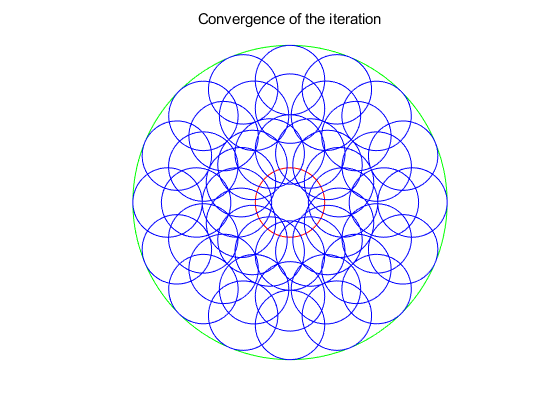

  objectRecover=ifft2(ifftshift(objectRecoverFT));
  Result = abs(objectRecover);
  Recon_phase = angle(objectRecover);
  resultFT = log(abs(objectRecoverFT));
  axis off; axis square
  gt = XxNorm(object_original,0,100);
  Result = XxNorm(Result,0,100);
  Result = uint16(Result* 65535);  
  imwrite(Result,[save_test_path '\' num2str(kkk) '.tif']);
end

mean(time)

ans = 0.5456